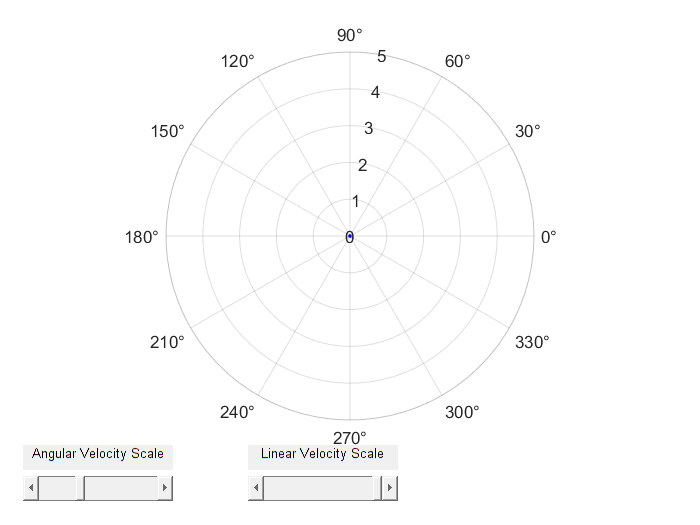

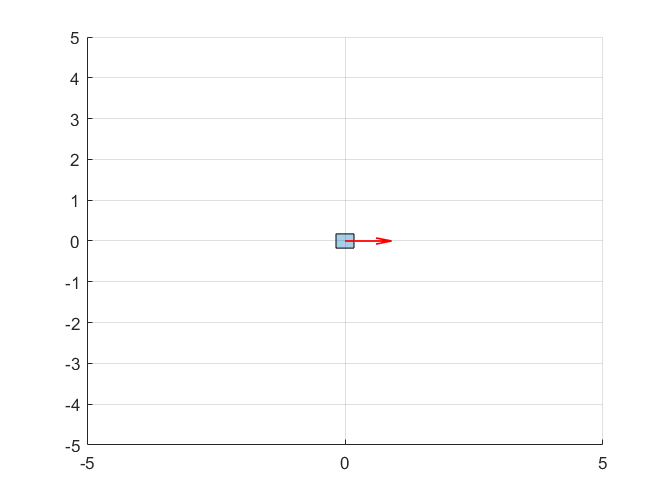


close all;

%Connect to your Neato or the Simulator - choose one or the other
[sensors,vels]=neatoSim(); %uncomment for simulator
%[sensors,vels]=neato('192.168.16.100') %uncomment for physical neato
pause(5) %wait a bit for the robot to start up

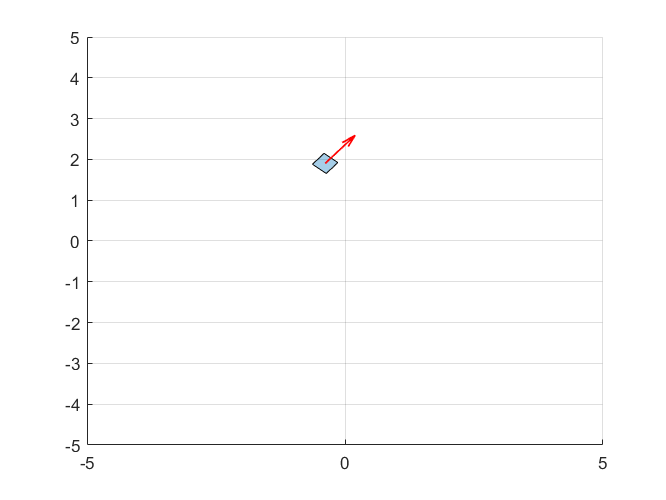



tic %%start your timer in Matlab
sec=toc; %t updates as the time since you started
max_points=3000;
encoder_data=zeros(max_points,3);
iter=0;

while sec<16
    iter=iter+1;
    sec=toc;%t updates as the time since you started
    if iter<=max_points
        encoder_data(iter,:)=[sec,sensors.encoders(1),sensors.encoders(2)];
    end 
    
    velocity_left_only_last = velocity_left(3);
    velocity_right_only_last = velocity_right(3);

    vl = double(subs(velocity_left_only_last,{t},{sec}));
    vr = double(subs(velocity_right_only_last,{t},{sec}));


    vels.lrWheelVelocitiesInMetersPerSecond=[vl,vr]; 
    %pause(.01) %you can add a short delay to be safe/for communication lag. 
end

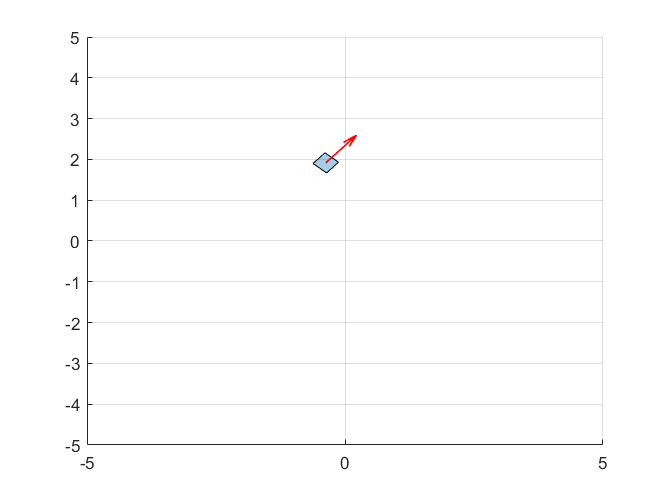

encoder_data=encoder_data(1:iter,:);
vels.lrWheelVelocitiesInMetersPerSecond=[0,0];
pause(1);